# Lagrange Formulation

## 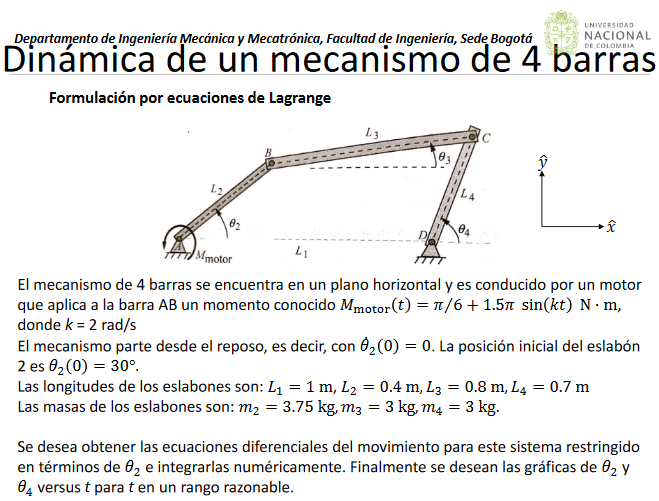

## Variables

syms t theta_2 theta_3 theta_4 lambda_1 lambda_2
syms theta_2_diff theta_3_diff theta_4_diff
L1 = 1;
L2 = 0.4;
L3 = 0.8;
L4 = 0.7;
m2 = 3.75;
m3 = 3;
m4 = 3;
theta_2_0 = deg2rad(30);
theta_2_diff_0 = 0;


## Position and Velocity

% Closure Equations
% Position
ce1=L2*cos(theta_2)+L3*cos(theta_3)-L4*cos(theta_4)-L1;
ce2=L2*sin(theta_2)+L3*sin(theta_3)-L4*sin(theta_4);
% velocity (Derivative respect to time constructed with variables and partial derivatives)
ce1_diff=diff(ce1,theta_2)*theta_2_diff + diff(ce1,theta_3)*theta_3_diff + diff(ce1,theta_4)*theta_4_diff;
ce2_diff=diff(ce2,theta_2)*theta_2_diff + diff(ce2,theta_3)*theta_3_diff + diff(ce2,theta_4)*theta_4_diff;

% Matrix representation
A_diff = [diff(ce1,theta_3) diff(ce1,theta_4);...
          diff(ce2,theta_3) diff(ce2,theta_4)];
B_diff = [-diff(ce1,theta_2)*theta_2_diff; -diff(ce2,theta_2)*theta_2_diff];

% Aceleration
%ce1_diff2=diff(ce1_diff,theta_2) + diff(ce1_diff,theta_3) + diff(ce1_diff,theta_4);
%ce2_diff2=diff(ce2_diff,theta_2) + diff(ce2_diff,theta_3) + diff(ce2_diff,theta_4);

lagrange_matrix = [ ((L2^2)*m2/3) 0 0 (L2*sin(theta_2)) -L2*cos(theta_2);...
                  0 ((L3^2)*m3/3) -(L3*L4*cos(theta_4-theta_3)*m3/2) (L3*sin(theta_3)) -(L3*cos(theta_3));...
                  0 -(L3*L4*cos(theta_4-theta_3)*m3/2) ((L4^2)*(m4/3 + m3)) -(L4*sin(theta_4)) (L4*cos(theta_4));...
                  (L2*sin(theta_2)) (L3*sin(theta_3)) -(L4*sin(theta_4)) 0 0;...
                  (L2*cos(theta_2)) (L3*cos(theta_3)) -(L4*cos(theta_4)) 0 0];
lagrange_vector = [ pi/6 + 1.5*sin(2*t); 
                   -(m3/2)*L3*L4*(theta_4_diff^2)*sin(theta_4-theta_3);...
                    (m3/2)*L3*L4*(theta_3_diff^2)*sin(theta_4-theta_3);...
                    (L4*(theta_4_diff^2)*cos(theta_4))-(L3*(theta_3_diff^2)*cos(theta_3))-(L2*(theta_2_diff^2)*cos(theta_2));...
                   -(L4*(theta_4_diff^2)*sin(theta_4))+(L3*(theta_3_diff^2)*sin(theta_3))+(L2*(theta_2_diff^2)*sin(theta_2))];
theta2_diff_exp = @(t, y) [y(2); (3/(m2*(L2^2)))*(L2*sin(y(1))*lambda_1 - L2*cos(y(2))*lambda_2 -  (pi/6 + 1.5*sin(2*t))) ];


steps = 200;
max_time = 2;
theta_result = zeros(steps, 3);
theta_diff_result = zeros(steps, 3);
theta_diff2_result = zeros(steps, 3);
theta_2_val = theta_2_0;
theta_2_diff_val = theta_2_diff_0;


for step = 0:steps
    % 
    i_time = step*(max_time/steps);
    % Calcular posicion
    sol = solve([subs(ce1,theta_2,theta_2_val), subs(ce2,theta_2,theta_2_val)],[theta_3,theta_4]);
    theta_result(step+1,:) = [theta_2_val, double(sol.theta_3(2)),double(sol.theta_4(2))];
    % Calcular velocidad
    A_diff_sub = subs(A_diff,[theta_2,theta_3,theta_4],theta_result(step+1,:));
    B_diff_sub = subs(B_diff,[theta_2,theta_3,theta_4],theta_result(step+1,:));
    sol = linsolve(A_diff_sub,subs(B_diff_sub,theta_2_diff,theta_2_diff_val));
         
    theta_diff_result(step+1,:) = [theta_2_diff_val, double(sol(1)),double(sol(2))];
    % Solucionar el sistema de Lagrange
    lagrange_matrix_sub = subs(lagrange_matrix,[theta_2,theta_3,theta_4],theta_result(step+1,:));
    lagrange_vector_sub = subs(lagrange_vector,[theta_2,theta_3,theta_4],theta_result(step+1,:));
    lagrange_vector_sub = subs(lagrange_vector_sub,[theta_2_diff, theta_3_diff, theta_4_diff],theta_diff_result(step+1,:));
    sol = linsolve(subs(lagrange_matrix_sub,t,i_time),subs(lagrange_vector_sub,t,i_time));
    theta_diff2_result(step+1,:) = [double(sol(1)),double(sol(2)),double(sol(3))];
    % Calcular nuevos theta2 y theta2_diff mediante integracion numerica (aproximacion trapezoidal)
    
    integration_step = (max_time/steps);   
    lambda_1 = double(sol(4));
    lambda_2 = double(sol(5));
    theta2_diff_exp = @(t, y) [y(2); (3/(m2*(L2^2)))*(-L2*sin(y(1))*lambda_1 + L2*cos(y(1))*lambda_2 + (pi/6 + 1.5*sin(2*t))) ];
    init_values = [theta_result(step+1,1); theta_diff_result(step+1,1)];
    
    [t_val,y_val]= ode45(theta2_diff_exp,[i_time i_time+integration_step], init_values);
    theta_2_val = y_val(end,1);
    theta_2_diff_val = y_val(end,2);
    %disp(rad2deg(theta_2_val))
    %disp(rad2deg(theta_2_diff_val))

     
    % if step == 0
    %     theta_2_diff_val = deg2rad(0.91531);        
    % else
    %     theta_2_diff_val = theta_diff_result(step+1,1) + (integration_step*(theta_diff2_result(step+1,1)+theta_diff2_result(step,1))/2);      
    % end
    % 
    % theta_2_val = theta_result(step+1,1) + (integration_step*(theta_2_diff_val+theta_diff_result(step+1,1))/2);
    % 

    msg = ['iteration:', num2str(step), ', Time: ', num2str(i_time),'.'];
    disp(msg);
end

iteration:0, Time: 0.
iteration:1, Time: 0.01.
iteration:2, Time: 0.02.
iteration:3, Time: 0.03.
iteration:4, Time: 0.04.
iteration:5, Time: 0.05.
iteration:6, Time: 0.06.
iteration:7, Time: 0.07.
iteration:8, Time: 0.08.
iteration:9, Time: 0.09.
iteration:10, Time: 0.1.
iteration:11, Time: 0.11.
iteration:12, Time: 0.12.
iteration:13, Time: 0.13.
iteration:14, Time: 0.14.
iteration:15, Time: 0.15.
iteration:16, Time: 0.16.
iteration:17, Time: 0.17.
iteration:18, Time: 0.18.
iteration:19, Time: 0.19.
iteration:20, Time: 0.2.
iteration:21, Time: 0.21.
iteration:22, Time: 0.22.
iteration:23, Time: 0.23.
iteration:24, Time: 0.24.
iteration:25, Time: 0.25.
iteration:26, Time: 0.26.
iteration:27, Time: 0.27.
iteration:28, Time: 0.28.
iteration:29, Time: 0.29.
iteration:30, Time: 0.3.
iteration:31, Time: 0.31.
iteration:32, Time: 0.32.
iteration:33, Time: 0.33.
iteration:34, Time: 0.34.
iteration:35, Time: 0.35.
iteration:36, Time: 0.36.
iteration:37, Time: 0.37.
iteration:38, Time: 0.38.
it

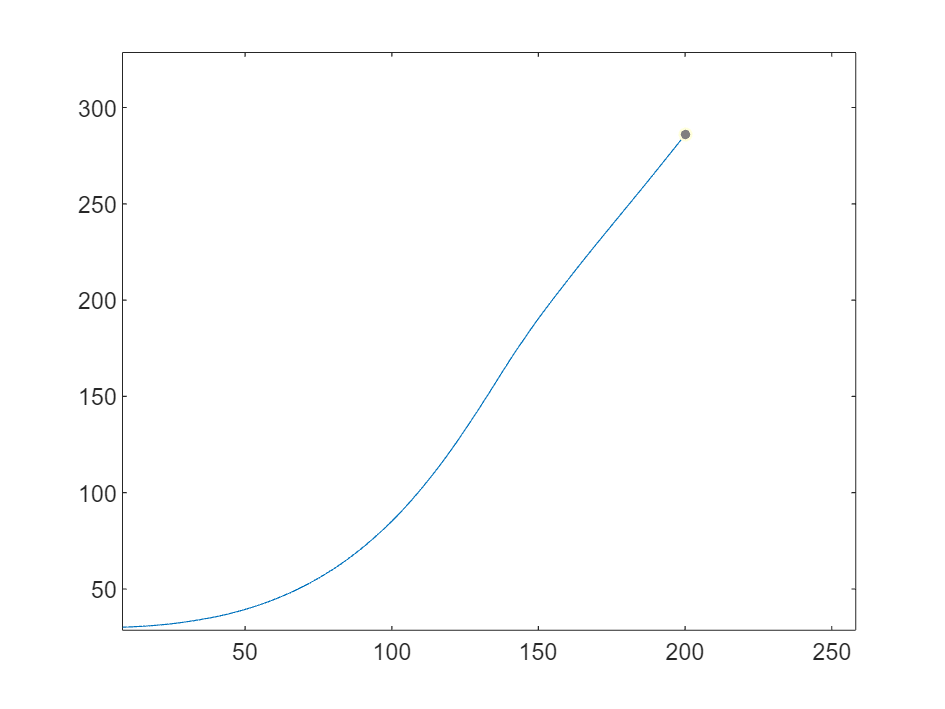

plot(rad2deg(theta_result(:,1)));